# Monte Carlo simulation of the Dickey Fuller Distribution

This script shows how to reconstruct the distribution and critical values of the Dickey-Fuller test for a unit root. For simplicity and exposition, we consider only the simplest of cases: an AR(1) process with no constant.

It also serves as an illustration of the following results: 

(i) Biased but consistent estimators for stationary processes: when the process             is stationary, the estimator for the AR(1) coefficient is biased in small samples (especially when the AR(1) coefficient is close to 1) but consistent as $T\rightarrow\infty$

(ii) the Central Limit Theorem (under stationarity): as $T\rightarrow\infty$ the simulated density of the estimates converges to that of a t-distributed variable

(iii) the non-standard distribution of the Dickey-Fuller test statistics at the null hypothesis of a unit root: When there is a unit root, the simulated density of the AR(1) coefficient does *not* converge to that of a t-distributed variable, regardless of the size of the time sample available.

### The Data Generating Process

The true data generating process (DGP) is given by:


$$y_t = a_1y_{t-1}+\varepsilon_t$$


with 


$$\varepsilon_t\underset{iid}{\sim} N(0,1) $$


where $a_1\in[0,1]$.

(Note: in principal, a "negative unit root" can exist, but it is not relevant to real-world economic applications)

The Dickey-Fuller test equation is given by subtracting $y_{t-1}$ from both sides of the difference equation above:


$$\triangle y_t = \gamma y_{t-1}+\varepsilon_t$$


where $\gamma = a_1 - 1$.

### Consider the following exercises:

For each of the following, keep the replications constant (e.g. $N=1000$), and evaluate how close the estimated coefficients, simulated critical values and simulated densities are to those predicted by classical theory

- Start off with a stationary process with a low autoregressive coefficient (e.g. $a_1=0.1$) and a small time sample (e.g. $T=100$) and 

- Next, keep the time sample small, but make the process very persistent, but still stationary (e.g. $a_1=0.9$).

- Keep the process persistent and stationary but increase the time sample (e.g. $T=1000$)

- Set the time sample small again, but make the process a random walk (i.e. $a_1 = 1$

- Keep the unit root process, but set the time sample large.

### Set parameters of true DGP

Autoregressive coefficient $a_1$

a1=0.1;  

The true value of the coefficient in the test equation $\gamma$

g=a1-1; 

Time sample size 

T=1000; 

Number of Monte Carlo replications (how many samples of T periods to examine). Larger than 1000 makes the code quite slow (it was not written for efficiency).

N=1000;

Level of significance (nominal size of test, probability of making a type I error):

alph=0.05;

## Generate the data

#### Draw stochastic terms

epsilon=randn(T+1,N); 

The rows of a specific column contain the sequence of draws of the white-noise error for a specific sample. Each column contains an independent sample of $T$ epsilon draws.

(We create $T+1$ rows, as we will discard the first to deal with the lagged dependent variable when we create the data)

#### Create placeholders to store results

Placeholders for data:

y=zeros(size(epsilon)); % the untransformed time series
Ly=zeros(size(epsilon));% the lag of the time series
Dy=zeros(size(epsilon));% the difference of the time series

Placeholders for estimates:


ghat=zeros(N,1);    % the N different OLS estimates of the gamma parameter
s2=zeros(N,1);      % s squared - the sample variance of ehat - the fector of residuals
se_ghat=zeros(N,1); % standard errors of the OLS estimator
t_ghat=zeros(N,1);  % t values

#### Data generation loop (all N samples simultaneously)

for t=2:T+1
    y(t,:)=a1*y(t-1,:)+epsilon(t,:);
    Ly(t,:)=y(t-1,:);
    Dy(t,:)=y(t,:)-y(t-1,:);
end

#### Data generation loop (sample by sample)

(For illustrative puposes.)

 The two data generation loops give exactly the same answers, the one below is slower.

% for n=1:N
%     for t=2:T
%         y(t,n)=a1*y(t-1,n)+epsilon(t,n);
%         yL(t,n)=y(t-1,n);
%         Dy(t,n)=y(t,n)-y(t-1,n);
%     end
% end

Drop first entry (just a placeholder, not real data)

y=y(2:end,:);
Ly=Ly(2:end,:);
Dy=Dy(2:end,:);

#### Plot all of the time paths

For each different choice of $a_1$, take note of the range and constancy of variation.

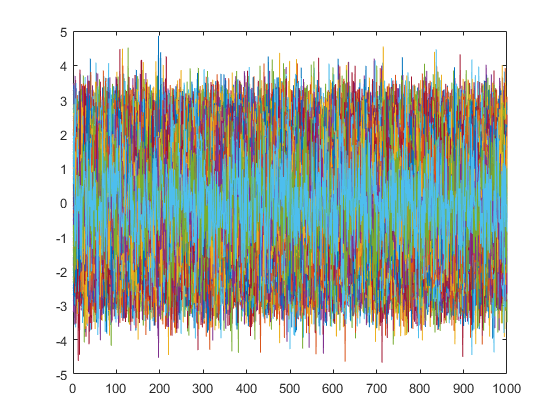

figure
plot(y)

## Estimations

#### Regression loop (sample by sample)

Estimate the $\gamma$ coefficient, the residuals, the residual sample variance and the t-statistics. This code computes the OLS estimates directly using their formulas for illustration. There are faster/more efficient ways of doing this.

X=Ly;   % the only regressor is the lagged dependent variable
for i=1:N
    ghat(i)=(X(:,i)'*X(:,i))\(X(:,i)'*Dy(:,i)); % OLS estimator evaluated for each sample
    ehat=Dy(:,i)-X(:,i)*ghat(i);                % residuals = actual - fitted;
    s2(i)=ehat'*ehat/(T-1);                     % sample variance of regression: mean sum of squared errors
    se_ghat(i)=sqrt((X(:,i)'*X(:,i))\s2(i));    % estimated standard error of the OLS estimator
    t_ghat(i)=(ghat(i)-g)/se_ghat(i);           % t-statistic for the null hypothesis: ghat = g - i.e. the true value
end

## Compute statistics of simulated distribution and t-distribution

#### Measures of centrality:

g                          % the true value of the parameter

g = -0.9000

ghat_mean = mean(ghat)     % mean of empirical distribution of OLS estimators for the N samples

ghat_mean = -0.9003

ghat_median = median(ghat) % median of empirical distribution of OLS estimators for the N samples

ghat_median = -0.9009

#### Kernel density estimates:

(Details in Advanced Cross-Section Econometrics - it's sufficient for our purposes to think about this as a "smoothed" histogram, or a semi-parametric approximation of the empirical density function)

[t_ghat_density, t_ghat_quantiles]=ksdensity(t_ghat); % estimated density function of the estimated t-statistics
[ghat_density, ghat_quantiles]=ksdensity(ghat);       % estimated density function of the coefficient estimates

Find the t-distribution density function evaluated at the same quantiles as the simulated density:

t_pdf=tpdf(t_ghat_quantiles,T-1);            

Since we are approximating continuous functions with infinite domain at a finite number of points, we have to standardize the values to make sure the area underneath the graph is equal to 1 (equivalently, that the sampled density values add to up to 1).

t_pdf=t_pdf/sum(t_pdf);
t_ghat_density = t_ghat_density/sum(t_ghat_density);
ghat_density = ghat_density/sum(ghat_density);

Find the critical values that imply a one-sided-test with size $\alpha$.

That is, find the t-statistic (simulated and standard) such that $\alpha$ percent of values are smaller. This is the $\alpha$th percentile of the distributions. For the simulated density, we have to find the empirical percentile. For the standard t-distribution, we have a function that yields exact results.               

t_crit_MC = prctile(t_ghat,alph*100)

t_crit_MC = -1.5947

t_crit_std = tinv(alph,T-1)

t_crit_std = -1.6464

size_at_std_crit = sum(t_ghat_density(t_ghat_quantiles<=t_crit_std))

size_at_std_crit = 0.0494

## Plot the results

The top panel is the estimated density of the computed t-statistics (in blue) and the density of the standard t-distribution (in green), along with the $(1-\alpha)\%$ confidence critical values (simulated and those from the standard t-distribution)

The bottom panel is the estimated density of $\hat{\gamma}_{OLS}$, along with the mean, median of the N estimates and the true $\gamma$

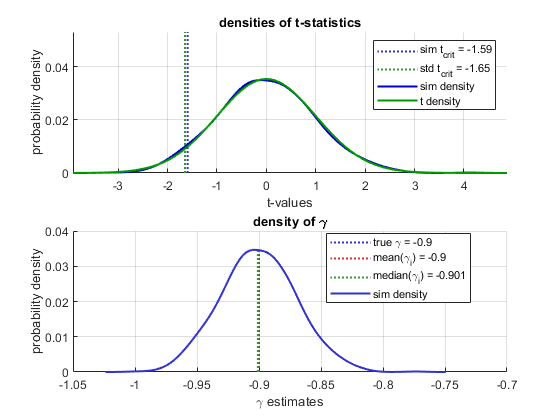

figure
clf
subplot(2,1,1) % display to 2 plots in a 2x1 matrix
hold on
line([t_crit_MC t_crit_MC],[0 1],'Color',[0.2,0.2,0.8],"LineWidth",1.5,"LineStyle",":")      % draw a dotted line that indicates the simulated critical t-value
line([t_crit_std t_crit_std],[0 1],'Color',[0.2,0.6,0.2],"LineWidth",1.5,"LineStyle",":")    % draw a cyan line that indicates the standard critical t-value
plot(t_ghat_quantiles,t_ghat_density/sum(t_ghat_density),'Color',[0,0,0.8],"LineWidth",1.5); % plot the estimated density of the t statistics
plot(t_ghat_quantiles,t_pdf,'Color',[0,0.6,0],"LineWidth",1.5)                               % plot the density of the t-distribution
legend(['sim t_{crit} = ',num2str(t_crit_MC,3)],['std t_{crit} = ',num2str(t_crit_std,3)],'sim density','t density')
title('densities of t-statistics')
axis([-inf,inf,0,max(t_pdf)*1.5])
xlabel('t-values')
ylabel('probability density')
grid on

subplot(2,1,2)
hold on
line([g g],[0 max(ghat_density)],'Color',[0.2,0.2,0.8],"LineWidth",1.5,"LineStyle",":")                 % plot a dotted line at the true gamma
line([ghat_mean ghat_mean],[0 max(ghat_density)],'Color',[0.8,0.2,0.2],"LineWidth",1.5,"LineStyle",":") % plot a dotted line at the empirical mean of the gamma estimates
line([ghat_median ghat_median],[0 max(ghat_density)],'Color',[0.2,0.6,0.2],"LineWidth",1.5,"LineStyle",":") %plot a dotted line at the empirical median of the gamma estimates
plot(ghat_quantiles,ghat_density,'Color',[0.2,0.2,0.8],"LineWidth",1.5);                                  % plot estimated density function of the gamma estimates
title('density of \gamma')
legend(['true \gamma = ',num2str(g,3)],['mean(\gamma_i) = ',num2str(ghat_mean,3)],['median(\gamma_i) = ',num2str(ghat_median,3)],'sim density','Location','best')
xlabel('\gamma estimates')
ylabel('probability density')
grid on

*Ignore this section until exercises 1-5 above are complete*

## Ergodicity (informal inspection)

We can now study the ergodicity of the process by comparing the different types of mean we mentioned in class. 

**Note: **This is *not *a formal test, just an informal visual appraisal of the available evidence.

*Ensemble mean*

Since we have $N$ realizations of the same process for $t=1,2,...,T$, we can construct the ensemble mean at each $t$. That is the mean across the different samples at a specific time $t$.  There is a different ensemble mean at every $t$.


$$ensemble\, mean(t)=\frac{1}{N}\sum_{i=1}^{N} y_t^{(i)}
 $$


ensemble_means = mean(y,2) 

ensemble_means =    -0.0194
    0.0291
   -0.0109
   -0.0513
    0.0172
    0.0283
   -0.0019
   -0.0276
    0.0146
    0.0417


For each sample $i$, we can also construct the mean across time. There is a different time mean for every sample $i$ of the process.


$$time\, mean(i)=\frac{1}{T}\sum_{t=1}^{T} y_t^{(i)}
 $$


time_means = mean(y,1)

time_means =     0.0229   -0.0089   -0.0622   -0.0049   -0.0540    0.0319    0.0122   -0.0579   -0.0038   -0.0276    0.0091   -0.0369   -0.0927   -0.0048   -0.0218   -0.0366    0.0020   -0.0106   -0.0176    0.0628    0.0360   -0.0337   -0.0677    0.0799   -0.0393    0.0114   -0.0430   -0.0358    0.0229    0.0390   -0.0435    0.0088    0.0610    0.0232    0.0524   -0.0017   -0.0291   -0.0066    0.0558   -0.0052   -0.0184   -0.0307   -0.0331   -0.0249    0.0544   -0.0141   -0.0486    0.0429   -0.0153   -0.0191


If a process is *ergodic, *the following holds:


$$lim_{N\rightarrow\infty}\frac{1}{N}\sum_{i=1}^{N} y_t^{(i)}
=lim_{T\rightarrow\infty}\frac{1}{T}\sum_{t=1}^{T} y_t^{(i)}
=\mathbb{E}(y_t)$$


Thus, if the process is ergodic, we expect the variability in the time means and ensemble means to be similar (for equal $T$ and $N$). If the variability of one is very different for the other, we would suspect that the process is not ergodic.

To see a clear result, set $T = N = 1000$ (at the top of the code) and compare this figure when $a_1=0.1$ and when $a_1=1$. Pay close attention to the difference in scale of the vertical axis in the two cases.

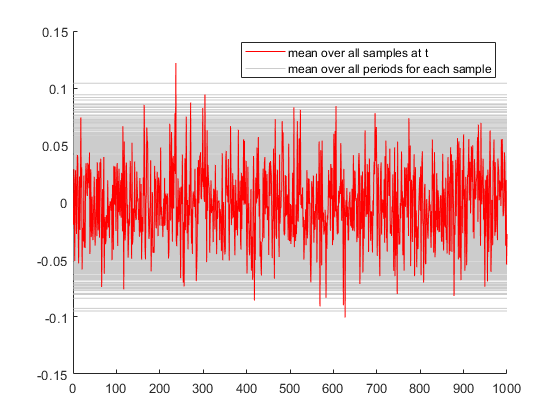

figure
hold on
plot(ensemble_means,'r')
plot(repmat(time_means,T,1),'Color',[0.8,0.8,0.8])
plot(ensemble_means,'r')
legend('mean over all samples at t','mean over all periods for each sample ')